[w,fs] = audioread("C:\Users\HP\Desktop\breath_phase.wav");

whale = timetable(seconds((0:length(w)-1)'/fs),w)

whale = 100×1 timetable
        Time           w   
    ____________    _______

    0초                  -1
    2.0833e-05초         -1
    4.1667e-05초         -1
    6.25e-05초           -1
    8.3333e-05초         -1
    0.00010417초         -1
    0.000125초           -1
    0.00014583초    0.99997
    0.00016667초    0.99997
    0.0001875초     0.99997
    0.00020833초    0.99997
    0.00022917초    0.99997
    0.00025초       0.99997
    0.00027083초    0.99997
    0.00029167초    0.99997
    0.0003125초     0.99997


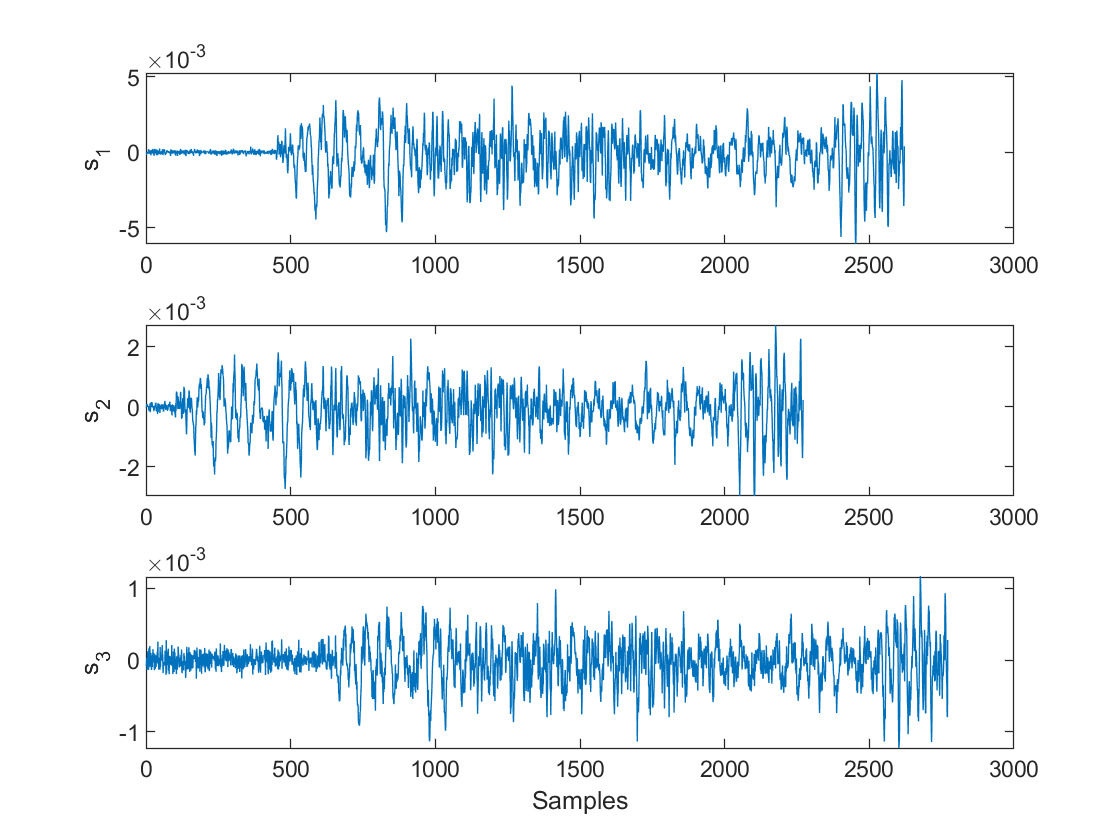

load relatedsig

ax(1) = subplot(3,1,1);
plot(s1)
ylabel('s_1')

ax(2) = subplot(3,1,2);
plot(s2)
ylabel('s_2')

ax(3) = subplot(3,1,3);
plot(s3)
ylabel('s_3')
xlabel('Samples')

linkaxes(ax,'x')


t21 = finddelay(s2,s1)

t21 = 350

t31 = finddelay(s3,s1)

t31 = -150

t32 = finddelay(s2,s3)

t32 = 500

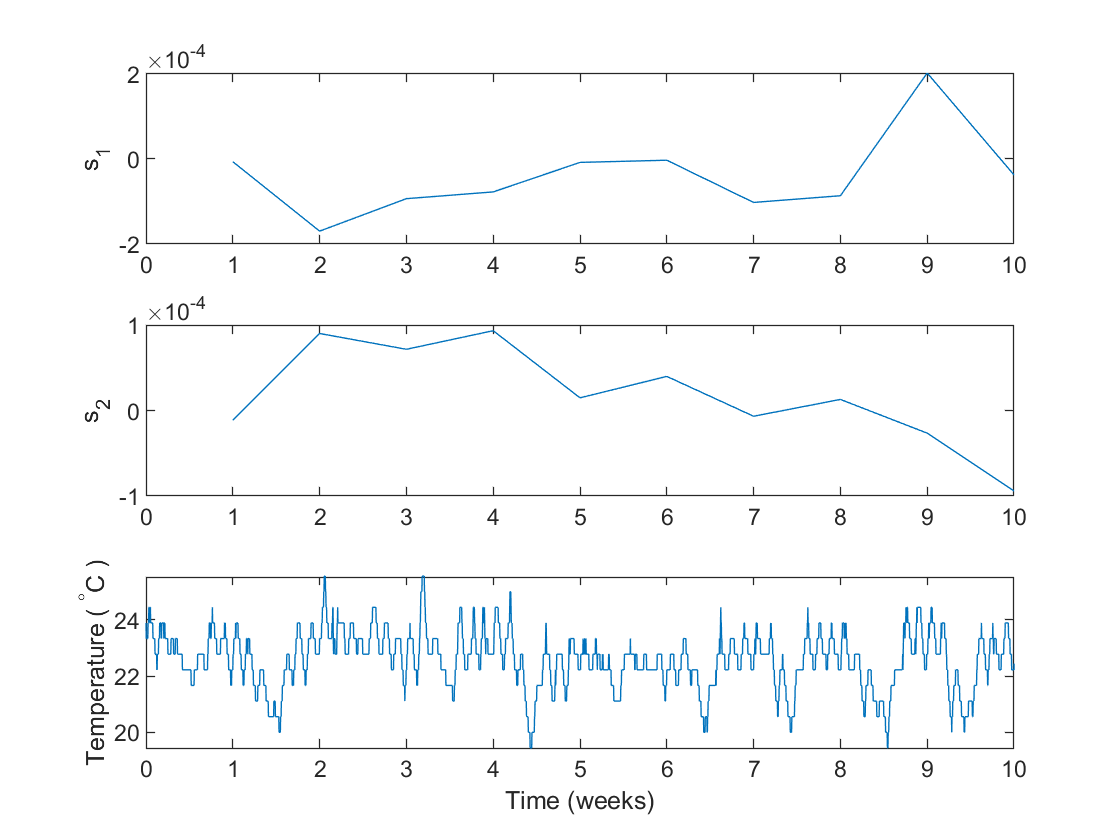

load officetemp

tempC = (temp - 32)*5/9;

fs = 2*24*7;
t = (0:length(tempC) - 1)/fs;

plot(t,tempC)
xlabel('Time (weeks)')
ylabel('Temperature ( {}^\circC )')
axis tight

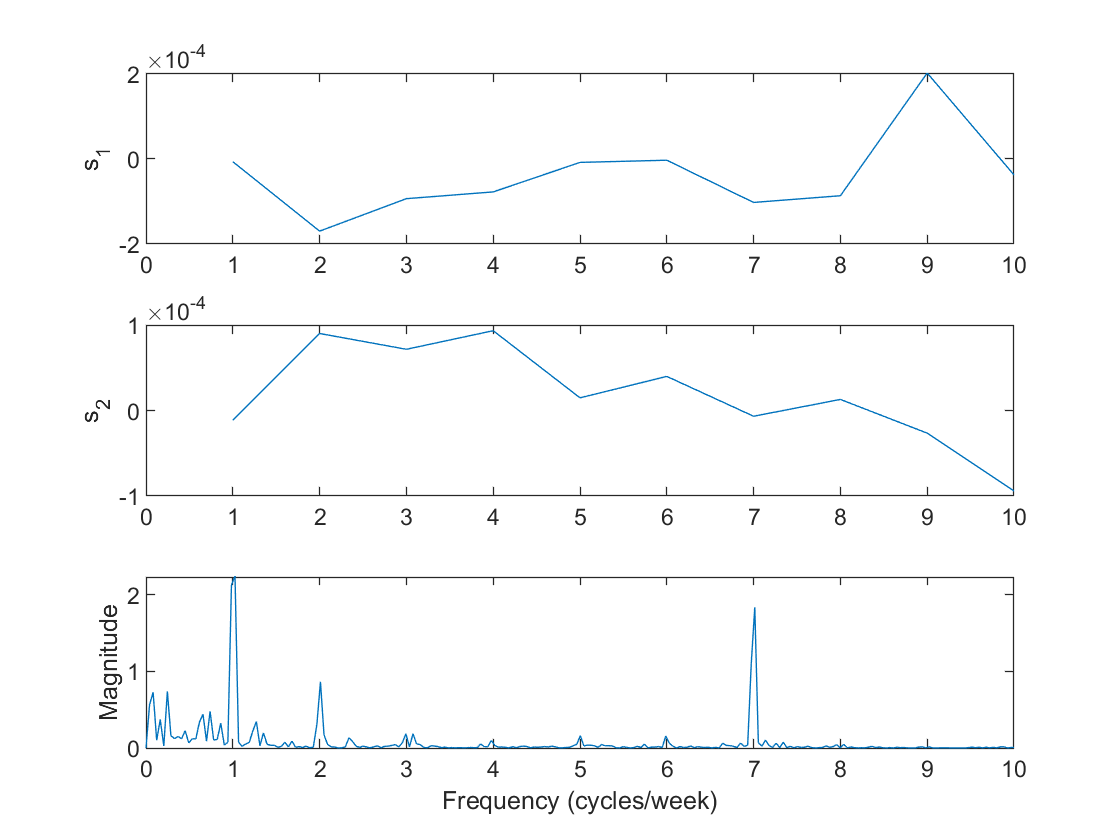

tempnorm = tempC - mean(tempC);

[pxx,f] = periodogram(tempnorm,[],[],fs);

plot(f,pxx)
ax = gca;
ax.XLim = [0 10];
xlabel('Frequency (cycles/week)')
ylabel('Magnitude')

Fs = 44100;
y = audioread("C:\Users\HP\Desktop\fast_walking.wav");


NFFT = length(y);
Y = fft(y,NFFT);
F = ((0:1/NFFT:1-1/NFFT)*Fs).';

magnitudeY = abs(Y);        % Magnitude of the FFT
phaseY = unwrap(angle(Y));  % Phase of the FFT

helperFrequencyAnalysisPlot1(F,magnitudeY,phaseY,NFFT)

'helperFrequencyAnalysisPlot1'을(를) 현재 폴더 또는 MATLAB 경로에서 찾을 수 없지만 다음 위치에 있습니다.
 C:\Users\HP\Documents\MATLAB\Examples\R2020a\signal\FrequencyAnalysisExample

MATLAB 현재 폴더 변경 또는 해당 폴더를 MATLAB 경로에 추가.


y1 = ifft(Y,NFFT,'symmetric');
norm(y-y1)

hplayer = audioplayer(y1, Fs);
play(hplayer);

Ylp = Y;
Ylp(F>=1000 & F<=Fs-1000) = 0;

helperFrequencyAnalysisPlot1(F,abs(Ylp),unwrap(angle(Ylp)),NFFT,...
  'Frequency components above 1 kHz have been zeroed')

ylp = ifft(Ylp,'symmetric');
hplayer = audioplayer(ylp, Fs);
play(hplayer);

% Take the magnitude of each FFT component of the signal
Yzp = abs(Y);
helperFrequencyAnalysisPlot1(F,abs(Yzp),unwrap(angle(Yzp)),NFFT,[],...
  'Phase has been set to zero')

yzp = ifft(Yzp,'symmetric');
hplayer = audioplayer(yzp, Fs);
play(hplayer);

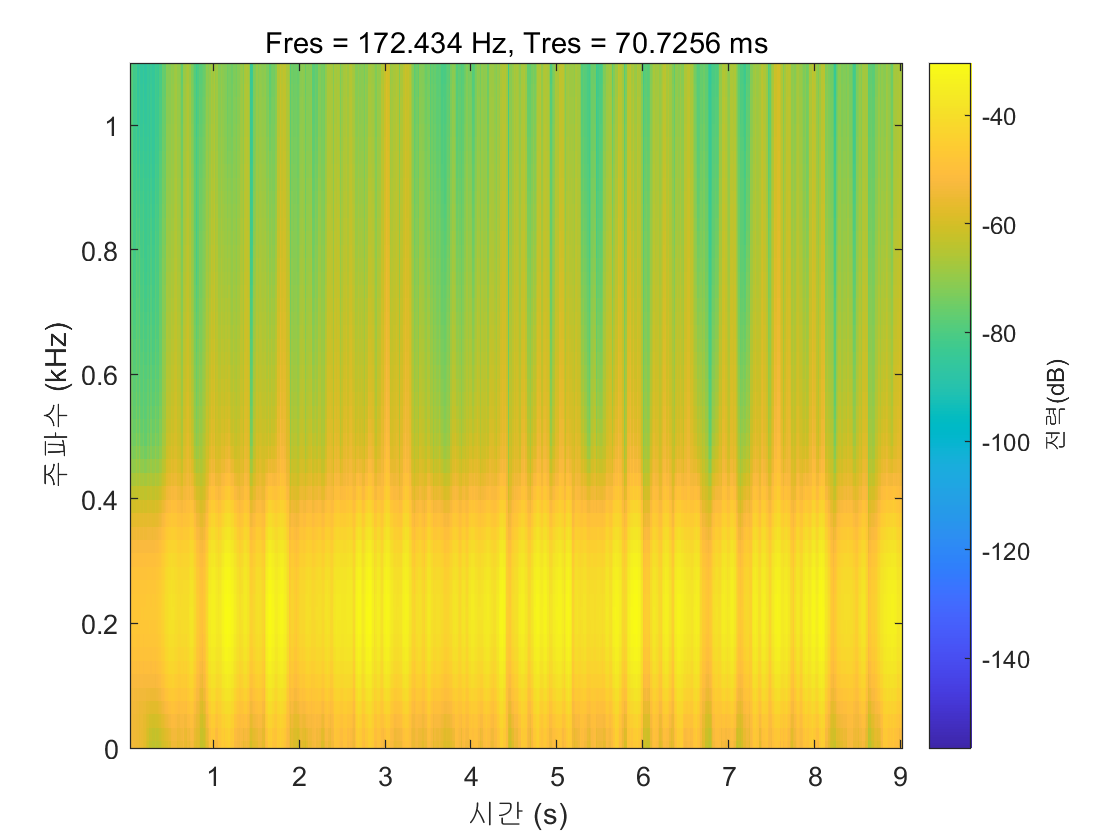

Fs = 44100;
y = audioread("C:\Users\HP\Desktop\fast_walking.wav");
pspectrum(y,Fs,'spectrogram')

xlim([0.03 9.03])
ylim([-0.0 1.1])

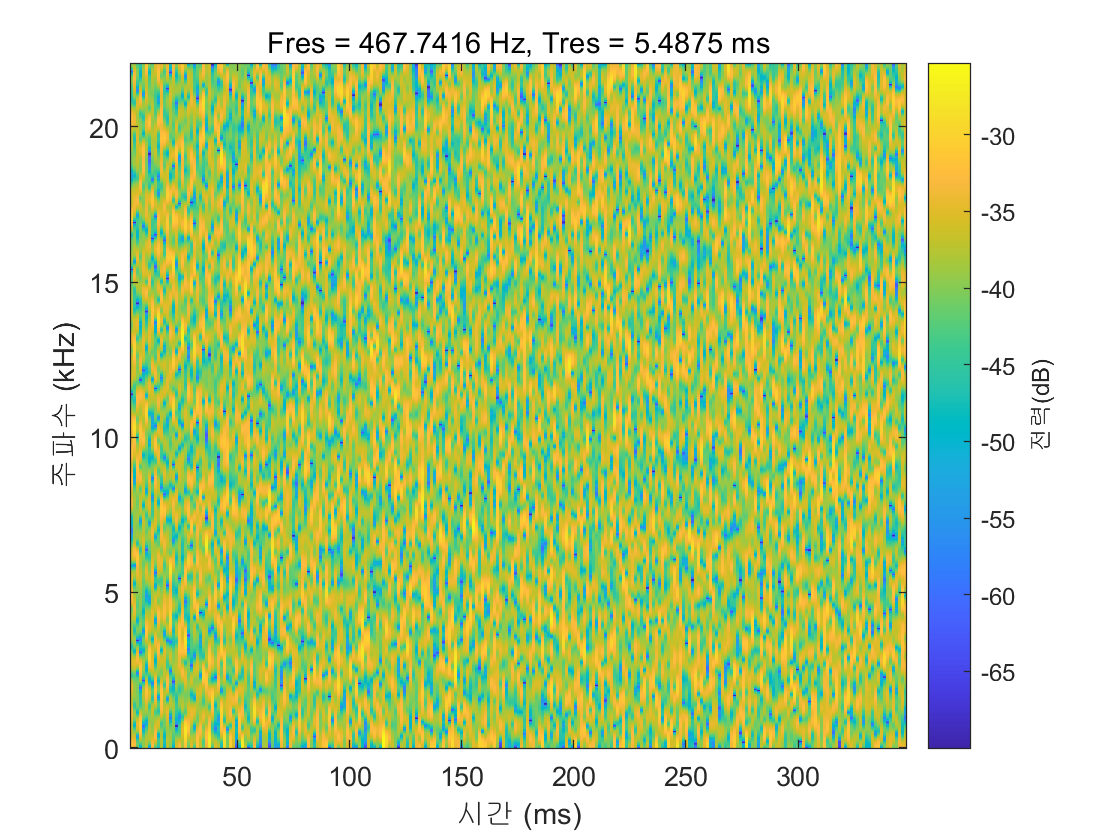

t = (0:length(y)-1)/Fs;
yNoise = y + 0.1*randn(size(y));
yChirp = yNoise(t<0.35);
pspectrum(yChirp,Fs,'spectrogram','MinThreshold',-70)

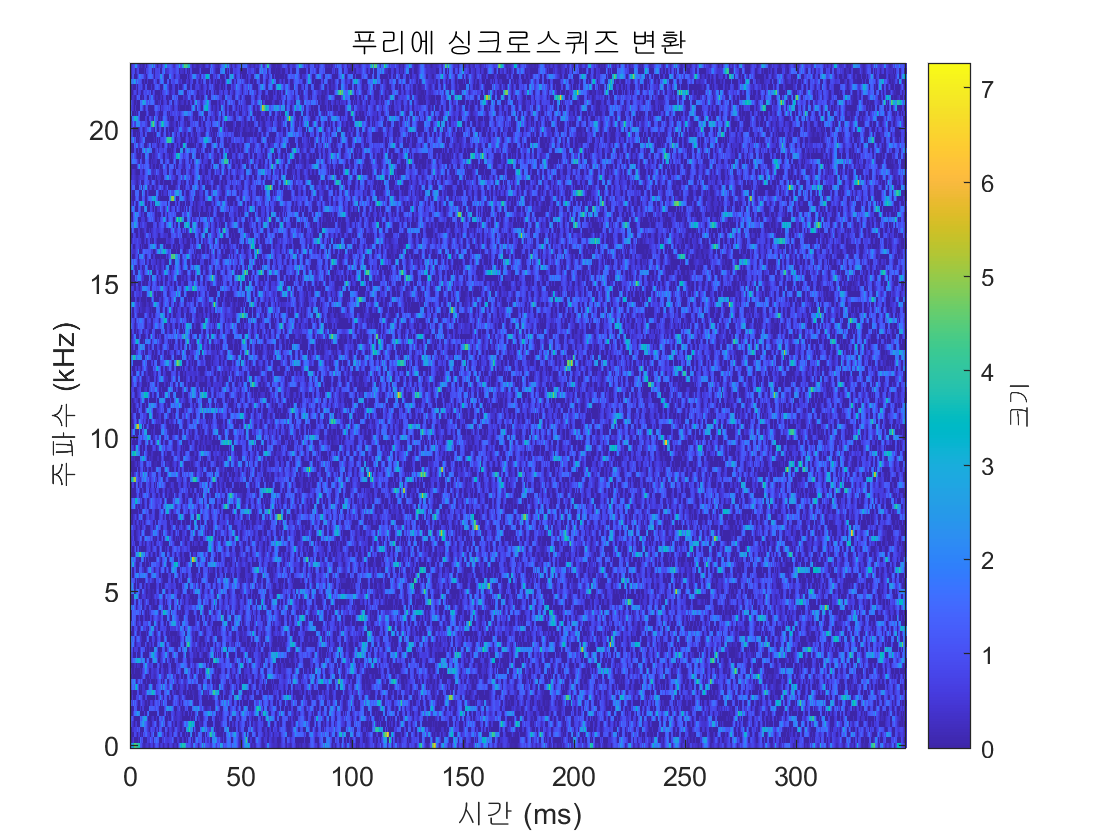

fsst(yChirp,Fs,'yaxis')

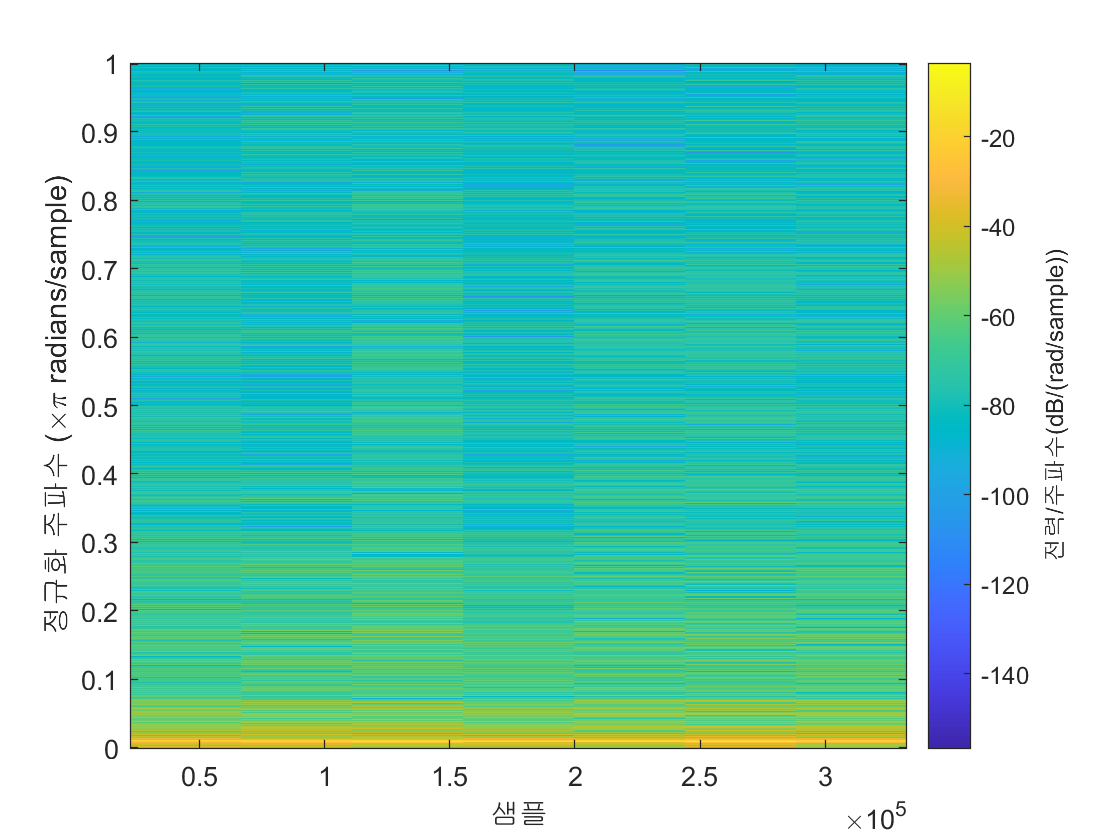

Fs = 44100;
y = audioread("C:\Users\HP\Desktop\fast_walking.wav");

s = spectrogram(y);

spectrogram(y,'yaxis')

fs, data = audioread("C:\Users\HP\Desktop\fast_walking.wav");

fs = 48000

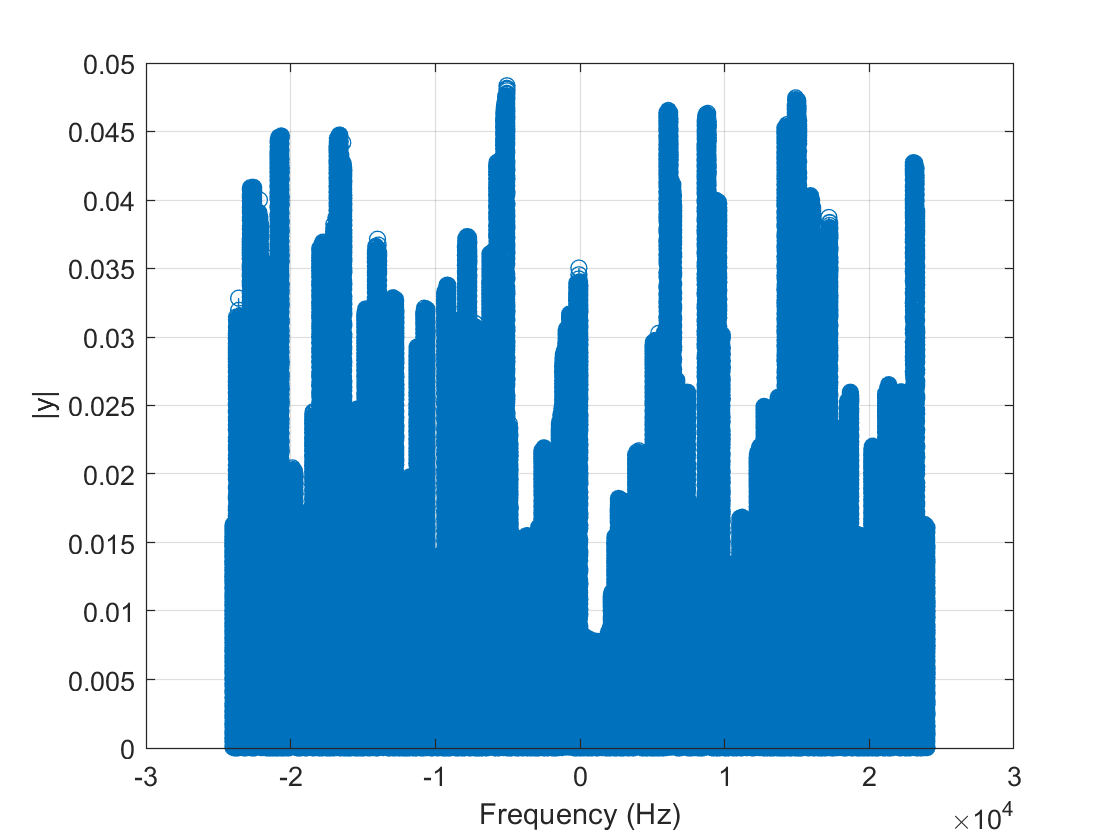

fft_data = fft(data);
fft_shift_data = fftshift(data);

ly = length(data);
f = (-ly/2:ly/2-1)/ly*fs;

stem(f,abs(fft_shift_data))
xlabel 'Frequency (Hz)'
%xlim([0 ly/2])
ylabel '|y|'
grid

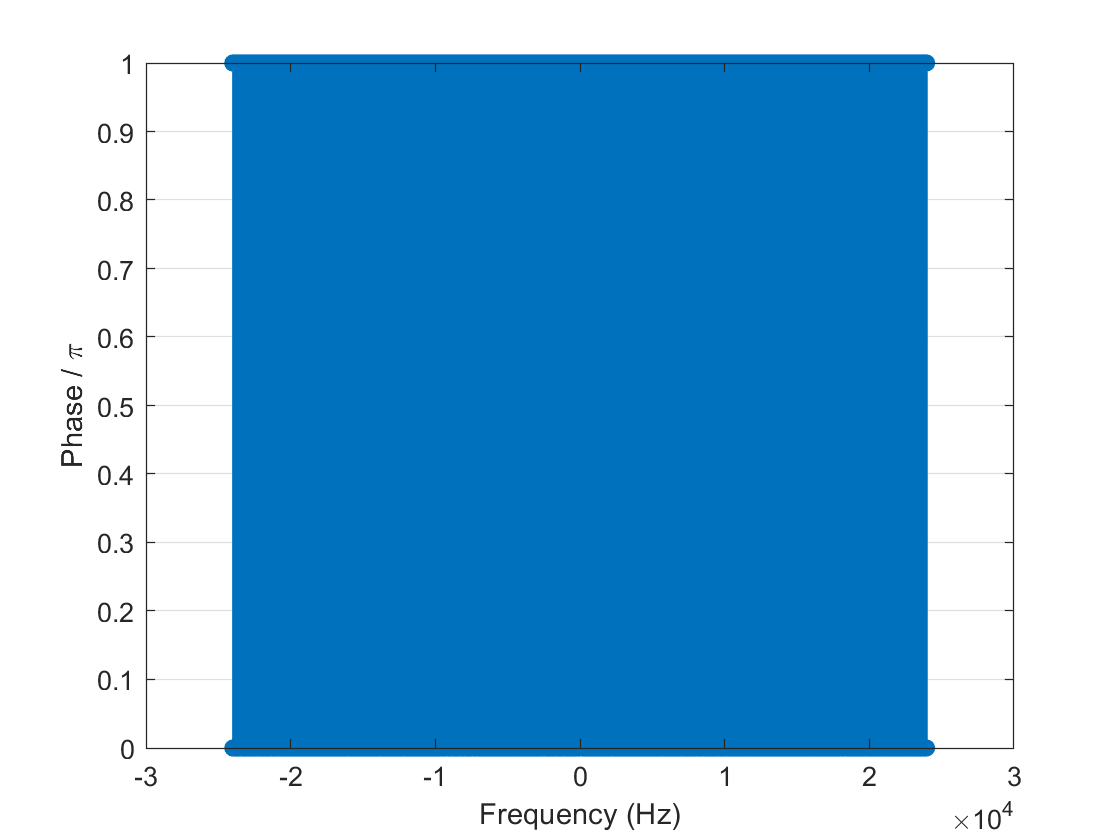


tol = 1e-6;
fft_shift_data(abs(fft_shift_data) < tol) = 0;

theta = angle(fft_shift_data);

stem(f,theta/pi)
xlabel 'Frequency (Hz)'
ylabel 'Phase / \pi'
grid